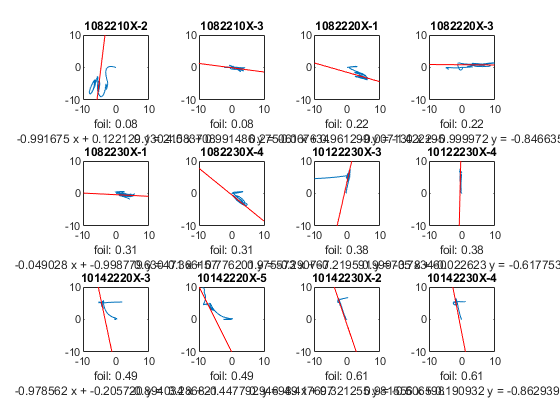


clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure(1)
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        ax(i) = subplot(3,4,i);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);;
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('10_oil_TopViewTraj.fig')

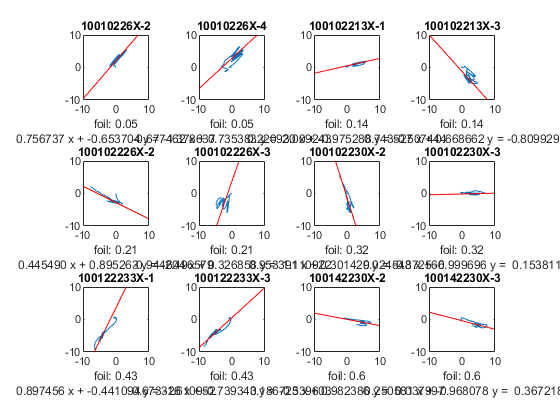

figure(2)
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(3,4,i-12);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('100_oil_TopViewTraj.fig')

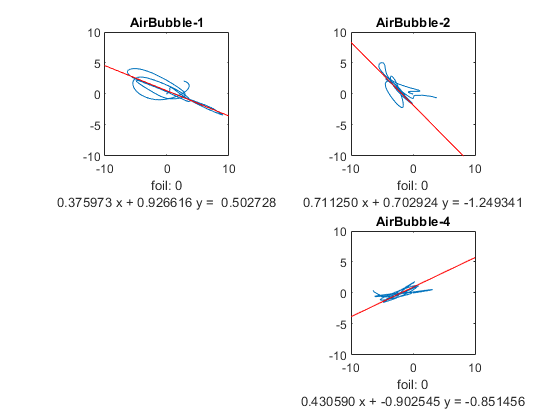

figure(3)
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        subplot(2,2,i-24);
        plot(x,y);
        hold on;
        plot(xline,yline,'-r');
        axis equal;
        title(FileName{i});
        xlim([-10, 10]);
        ylim([-10, 10]);
        xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d)})
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        save(path,'traj3D','Plane');
    end
end
savefig('Air_TopViewTraj.fig')